%SRA - Trabajo Practico de Laboratorio N°4
clc;
clear;
close all;


% Parametros de Entrada
fp=[800 1250]; %Banda de Paso [Hz]
fs=[200 5000]; %Banda de Rechazo [Hz]

Wp=2*pi*fp; %Banda de Paso [rad/s]
Ws=2*pi*fs; %Banda de Rechazo [rad/s]

Ap=0.25; %Atenuacion maxima en Banda de Paso [dB]
As=30; %Atenuacion minima en Banda de Rechazo [dB]


% Calculo de FT
[n,Wp]=cheb1ord(Wp,Ws,Ap,As,'s');
[num,den]=cheby1(n,Ap,Wp,'s');



Filtro=tf(num,den) %Funcion de transferencia calculada

Filtro =
 
                      1.642e07 s^2
  -----------------------------------------------------
  s^4 + 5080 s^3 + 9.586e07 s^2 + 2.006e11 s + 1.559e15
 
Continuous-time transfer function.



[sos,g] = tf2sos(num,den); %Descomponemos en bicuadrativas


%Implementacion como PasaAlto/PasaBajo
PasaBajo=tf(2*g*sos(1,1:3),sos(1,4:6))

PasaBajo =
 
         3.284e07
  -----------------------
  s^2 + 3184 s + 6.632e07
 
Continuous-time transfer function.



PasaAlto=tf(1/2*sos(2,1:3),sos(2,4:6))

PasaAlto =
 
         0.5 s^2
  ----------------------
  s^2 + 1896 s + 2.35e07
 
Continuous-time transfer function.



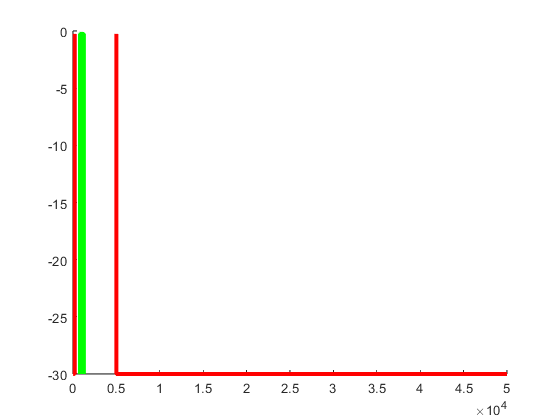


% Graficos
figure;
hold on;

%Especificaciones Filtro
plot([fs(1)/10 fs(1) fs(1)],[-As -As -Ap],'Color','r','LineWidth',3);
plot([fs(2) fs(2) fs(2)*10],[-Ap -As -As],'Color','r','LineWidth',3);
plot([fp(1) fp(1) fp(2) fp(2)],[-As -Ap -Ap -As],'Color','g','LineWidth',3);

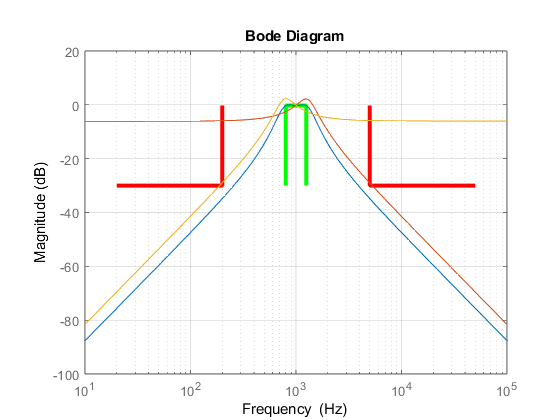

%Filtro
h = bodeplot(Filtro);
p = getoptions(h);
p.PhaseVisible='off';
p.FreqUnits='Hz';
p.Grid='on';
setoptions(h,p);
bode(PasaBajo);
bode(PasaAlto);

hold off;